# EE 451 Homework 5

# Lisa Jacklin

# 10/4/2023

## Problem 1

--> put in a image of hw problem 1 here

## Problem 2

## Problem 3

%Part a: moving_average_filter function creation!
%below is the code I setup.

%part b.
Fs3 = 1000;
Ts3 = 1/Fs3;
n = 2:1:50;


## Problem 4

load ekg.mat %to upload the data file from HW5
who %to determine what variables were loaded from the file


Your variables are:

Fs           Q            a            ekg60Fft     ekg60n       ekge60       elim60       n            
Fs3          Ts           b            ekg60filt    ekg60npad    ekgmin60     f0           t            
N            Ts3          ekg          ekg60filter  ekgFft       ekgpad       fft_signal   



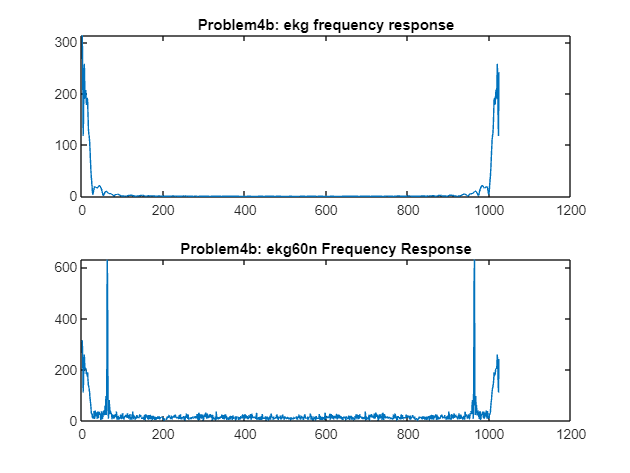


Fs = 1000;
Ts = 1/Fs; %sampling time
N = 800; %sample size for each 

t = 0:Ts:(N-1)*Ts; %time frame

subplot(2,1,1);
stem(t, ekg);
title("Problem 4a: ekg vs time");

subplot(2,1,2);
stem(t, ekg60n);
title("Problem 4a: ekg60n vs time");
%now, changing both ekg and ekg60n to digital frequency of 0<w<2pi and
%padding the signal until N = 1024. note that here we are suposed to
%utilize fft as instructed.

%first for ekg
ekgpad = [ekg, zeros(1,1024 - N)]; %could have used dft function here
ekgFft = fft(ekgpad);
subplot(2,1,1);
plot(abs(ekgFft));
title("Problem4b: ekg frequency response");

%now for ekg60n
ekg60npad = [ekg60n, zeros(1, 1024 - N)];
ekg60Fft = fft(ekg60npad);
subplot(2,1,2);
plot(abs(ekg60Fft));
title("Problem4b: ekg60n Frequency Response");


%now we are going to try and remove the peak at 60Hz, and minimize the
%random noise of the signal ekg60n.
n = 0:1:N-1;
elim60 = cos(2*pi*30*n*Ts);
ekgmin60 = ekg60n ;

% Apply Fast Fourier Transform (FFT)
subplot(2,1,2);
fft_signal = fft(ekgmin60);
ekge60 = dft(fft_signal, 1024);

Transformation matrix for DFT
  Columns 1 through 5

   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 - 0.0061i   0.9999 - 0.0123i   0.9998 - 0.0184i   0.9997 - 0.0245i
   1.0000 + 0.0000i   0.9999 - 0.0123i   0.9997 - 0.0245i   0.9993 - 0.0368i   0.9988 - 0.0491i
   1.0000 + 0.0000i   0.9998 - 0.0184i   0.9993 - 0.0368i   0.9985 - 0.0552i   0.9973 - 0.0736i
   1.0000 + 0.0000i   0.9997 - 0.0245i   0.9988 - 0.0491i   0.9973 - 0.0736i   0.9952 - 0.0980i
   1.0000 + 0.0000i   0.9995 - 0.0307i   0.9981 - 0.0613i   0.9958 - 0.0919i   0.9925 - 0.1224i
   1.0000 + 0.0000i   0.9993 - 0.0368i   0.9973 - 0.0736i   0.9939 - 0.1102i   0.9892 - 0.1467i
   1.0000 + 0.0000i   0.9991 - 0.0429i   0.9963 - 0.0858i   0.9917 - 0.1285i   0.9853 - 0.1710i
   1.0000 + 0.0000i   0.9988 - 0.0491i   0.9952 - 0.0980i   0.9892 - 0.1467i   0.9808 - 0.1951i
   1.0000 + 0.0000i   0.9985 - 0.0552i   0.9939 - 0.1102i   0.9863 - 0.1649i   0.97

Xk = 1.0e+03 *

   1.2556 + 0.0000i
   0.3134 - 0.0013i
  -0.0711 - 1.9413i
   1.1652 - 1.5906i
   0.3291 - 0.0058i
  -1.6203 - 0.5871i
  -0.2412 - 0.8324i
   0.4398 - 1.2675i
  -0.6659 + 0.9809i
  -1.2519 + 0.1543i


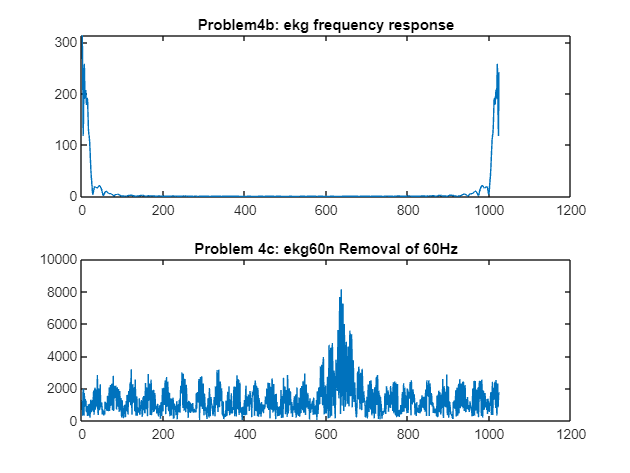

plot(abs(ekge60));
title("Problem 4c: ekg60n Removal of 60Hz");


%now, using filter(b,a,x) I can go ahead and filter the data of the
%function ekg60n to see if it matches or is close to ekg which is the ideal
%signal.
% Design a notch filter to remove the 60Hz component
f0 = 60; % Frequency to notch out (60Hz)
Q = 10;  % Quality factor (adjust as needed)
[b, a] = iirnotch(f0/(Fs/2), f0/(Fs/2)/Q); 
%note that iirnotch will let me use the frequency sample to determine where
%60hz is and will give me the coefficients for this!

ekg60filt = filter(b, a, ekg60n); %don't forget to transform again!
ekg60filter = dft(ekg60filt, 1024);

Transformation matrix for DFT
  Columns 1 through 5

   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 - 0.0061i   0.9999 - 0.0123i   0.9998 - 0.0184i   0.9997 - 0.0245i
   1.0000 + 0.0000i   0.9999 - 0.0123i   0.9997 - 0.0245i   0.9993 - 0.0368i   0.9988 - 0.0491i
   1.0000 + 0.0000i   0.9998 - 0.0184i   0.9993 - 0.0368i   0.9985 - 0.0552i   0.9973 - 0.0736i
   1.0000 + 0.0000i   0.9997 - 0.0245i   0.9988 - 0.0491i   0.9973 - 0.0736i   0.9952 - 0.0980i
   1.0000 + 0.0000i   0.9995 - 0.0307i   0.9981 - 0.0613i   0.9958 - 0.0919i   0.9925 - 0.1224i
   1.0000 + 0.0000i   0.9993 - 0.0368i   0.9973 - 0.0736i   0.9939 - 0.1102i   0.9892 - 0.1467i
   1.0000 + 0.0000i   0.9991 - 0.0429i   0.9963 - 0.0858i   0.9917 - 0.1285i   0.9853 - 0.1710i
   1.0000 + 0.0000i   0.9988 - 0.0491i   0.9952 - 0.0980i   0.9892 - 0.1467i   0.9808 - 0.1951i
   1.0000 + 0.0000i   0.9985 - 0.0552i   0.9939 - 0.1102i   0.9863 - 0.1649i   0.97

Xk = 1.0e+02 *

   3.2014 + 0.0000i
  -1.1395 - 2.0792i
  -0.9471 + 0.6608i
   0.4561 + 1.4156i
   1.6369 - 1.7286i
  -2.5212 - 0.3686i
   0.3696 + 2.1618i
   1.9588 - 0.2368i
  -0.5113 - 2.0227i
  -1.4393 + 1.3409i


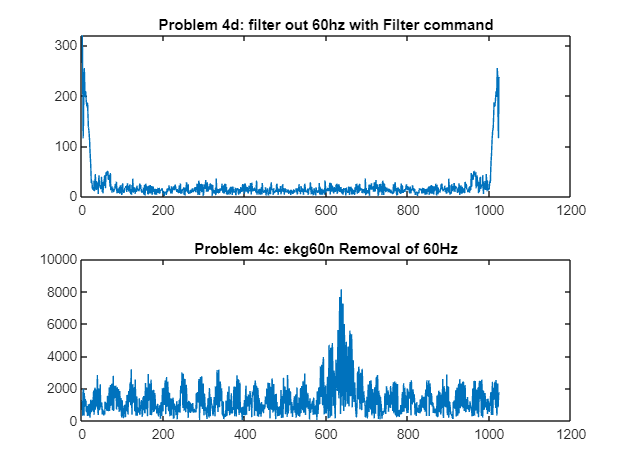

subplot(2,1,1);
plot(abs(ekg60filter));
title("Problem 4d: filter out 60hz with Filter command");

%comment on results:



## Problem 5